%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Script Name:    Elevation-Adjusted Race Pace Calculator
% Description:    
%   This MATLAB script reads a GPX file containing the latitude and 
%   longitude data for a race course, retrieves or loads elevation data 
%   (optionally using the Google Maps Elevation API), and computes 
%   elevation-adjusted running paces for segments of the course. 
%   The script performs the following steps:
%     - Reads GPX data and extracts latitude and longitude.
%     - Loads or queries elevation data for each course point.
%     - Calculates cumulative distance and elevation profile.
%     - Smooths the elevation data to reduce local fluctuations.
%     - Computes elevation gain for course segments.
%     - Estimates running pace for each segment based on elevation gain,
%       using both linear and exponential models.
%     - Scales segment paces to match a target total race time.
%     - Visualizes the elevation profile, segment paces, and segment times.
%
%   This tool is useful for runners and coaches to plan pacing strategies 
%   for hilly race courses, allowing for realistic adjustments based on 
%   terrain.
%
% Usage Notes:
%   - Requires the Mapping Toolbox for gpxread and geodetic calculations.
%   - For new courses, obtain a Google Maps Elevation API key and use the 
%     getElevations function to retrieve elevation data.
%   - Elevation data for the example course is loaded from a .mat file.
%
% Author:         Omkar Karve
% Date:           06-Aug-2025
% Version:        1.0
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Copyright (c) 2024 Omkar Karve
%
% Copyright (c) Omkar Karve
% 
% Permission is hereby granted, free of charge, to any person obtaining a copy
% of this software and associated documentation files (the "Software"), to use,
% copy, modify, and distribute the Software for personal, academic, or research
% purposes, provided that the above copyright notice and this permission notice
% appear in all copies.
% 
% Commercial use (including incorporation into proprietary products or commercial
% services) is NOT permitted without explicit written permission from the authors.
% To request commercial licensing, please contact the contributors.
% 
% Disclaimer of Warranty:
% THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR
% IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY,
% FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT.
% 
% Limitation of Liability:
% IN NO EVENT SHALL THE AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM,
% DAMAGES OR OTHER LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE,
% ARISING FROM, OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER
% DEALINGS IN THE SOFTWARE.
% 
% Health and Safety Disclaimer:
% THIS SOFTWARE IS INTENDED FOR EDUCATIONAL AND PLANNING PURPOSES ONLY. THE AUTHORS
% AND CONTRIBUTORS ARE NOT RESPONSIBLE OR LIABLE FOR ANY INJURY, HEALTH ISSUES, OR
% OTHER HARM THAT MAY RESULT FROM THE USE OF THIS SOFTWARE OR ANY DECISIONS MADE
% BASED ON ITS OUTPUT. USERS ASSUME ALL RISKS ASSOCIATED WITH ATHLETIC TRAINING
% AND COMPETITION.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clc;clear;
% --- Read the gpx file containing the course coordinates ---
% gpxData = gpxread("COURSE_387910445.gpx");

%% --- Get elevation from lat long using Google Maps Elevation API ---
%% Get keys at Google Maps Platform https://developers.google.com/maps/documentation/elevation/get-api-key?setupProd=prerequisites
%% Run the following lines only if gpx file changes. This has been run once for
%% COURSE_387910445.gpx and saved as COURSE_387910445_Elevation.mat

% [elevation, resolution] = getElevations(gpxData.Latitude, gpxData.Longitude, 'key', ...
%     'API_KEY_HERE');
load('COURSE_Elevation.mat'); % Load pre-saved elevation data

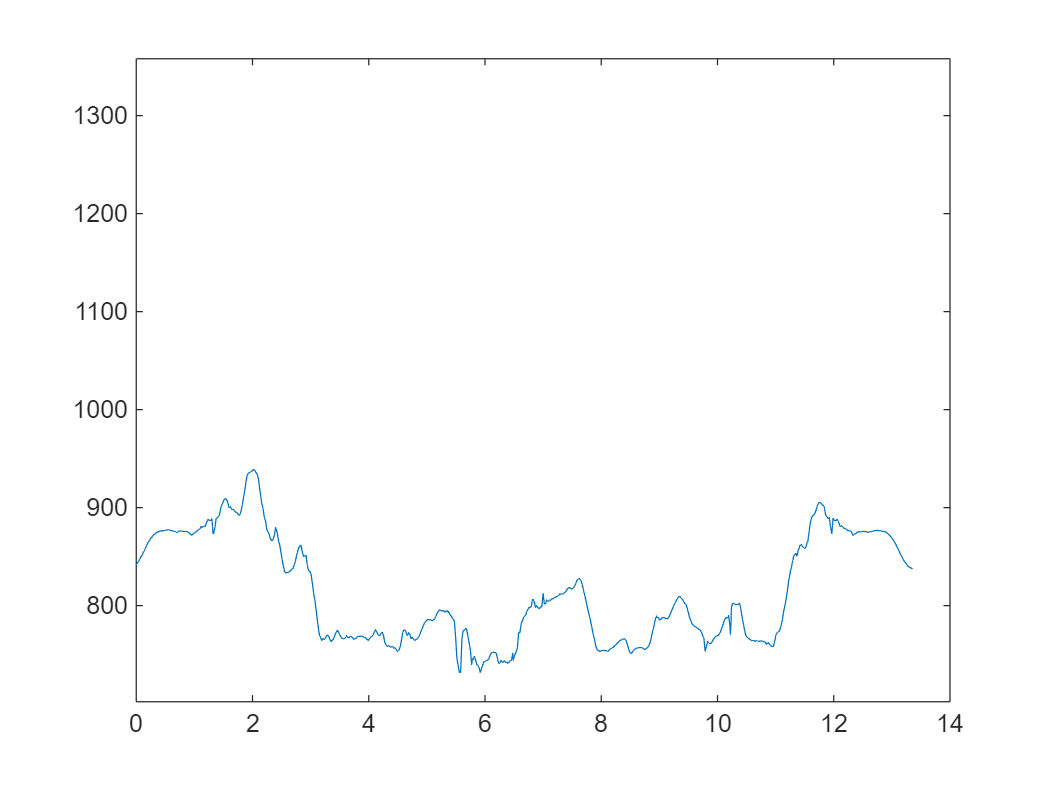

% --- Initialize distance array (in meters) ---
dist_mtr = zeros(width(gpxData.Longitude),1);

% --- Define the WGS84 ellipsoid for geodetic calculations ---
wgs84 = wgs84Ellipsoid;
dist_mtr(1) = 0;

% --- Compute cumulative distance along the course ---
for i=1:width(gpxData.Latitude)-1
    [arclen, ~] = distance(gpxData.Latitude(i), gpxData.Longitude(i), gpxData.Latitude(i+1), gpxData.Longitude(i+1), wgs84);
    dist_mtr(i+1) = arclen + dist_mtr(i);
end

% --- Convert distance from meters to miles ---
dist_miles = dist_mtr * 0.000621371;

% --- Convert elevation from meters to feet ---
elevation_feet = elevation * 3.28024;

% --- Plot raw elevation profile ---
plot(dist_miles,elevation_feet)
ylim([702 1358])

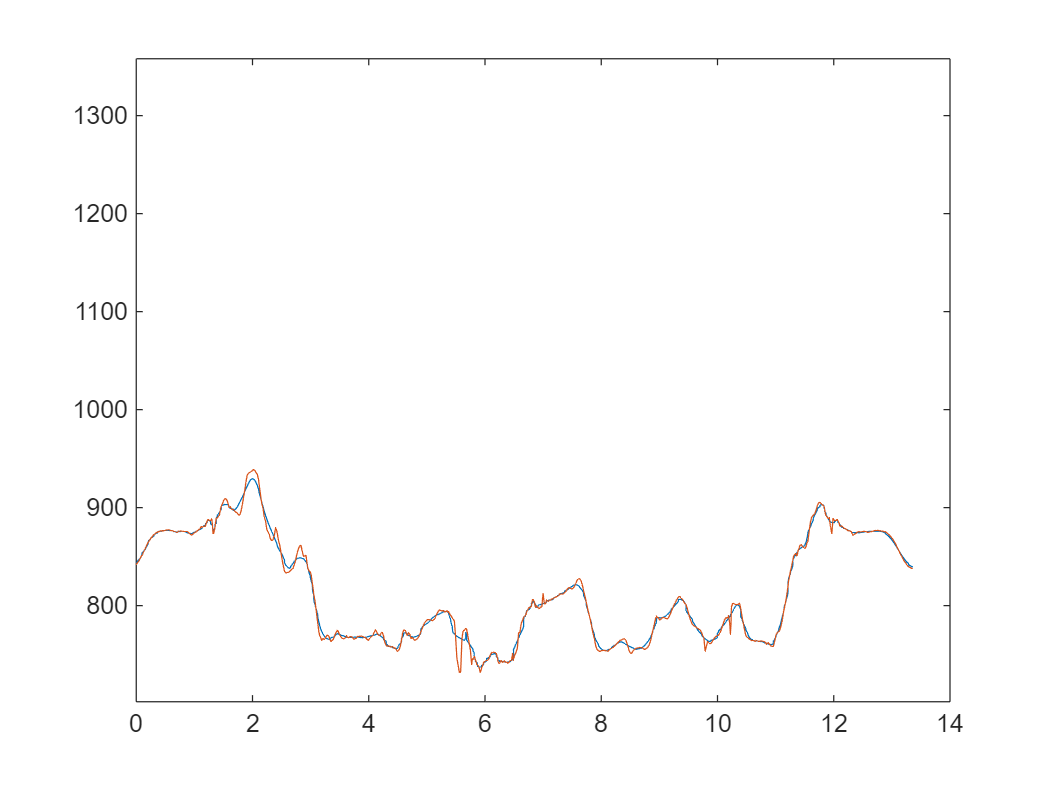

% --- Set target total race time (in minutes) ---
total_time_min = 125; % 2 hrs 5 min - desired race time

% --- Set window size for smoothing elevation profile ---
smooth_window = 15; % number of points in the data

% --- Smoothing elevation to reduce local fluctuations ---
elev_smooth = movmean(elevation_feet, smooth_window);

% --- Plot smoothed and raw elevation profiles for comparison ---
plot(dist_miles,elev_smooth)
ylim([702 1358])
hold on;
plot(dist_miles,elevation_feet);
hold off;

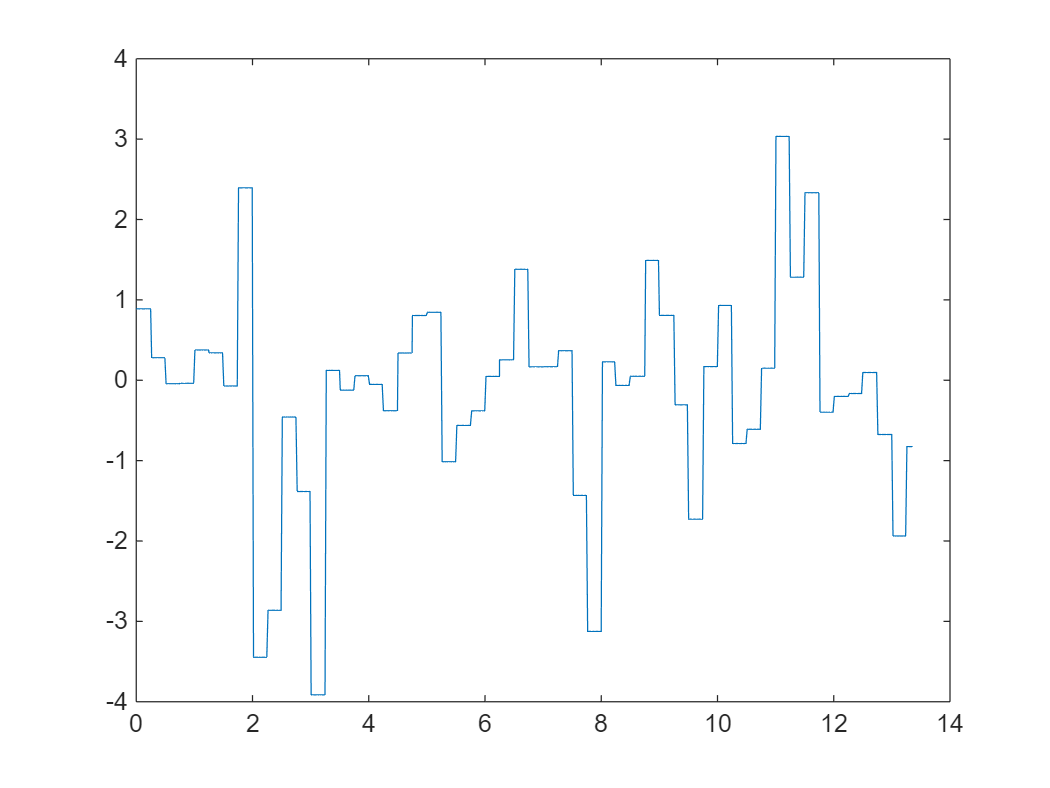

% --- Calculate elevation gain per segment (difference between points) ---
delta_elev = [0, diff(elev_smooth)];
delta_dist = [0, diff(dist_miles')];

% --- Only consider positive elevation changes (uphill) for gain ---
elev_gain = max(delta_elev, 0);

% --- Use raw elevation change (can be positive or negative) ---
gain_to_use = delta_elev;

% --- Set window size (in miles) for averaging elevation gain ---
window_size = 0.25; % miles

% --- Initialize array to hold average elevation gain per window ---
average_elev_gain = zeros(size(gain_to_use));

% --- Define window sections along the course ---
sections = dist_miles(1):window_size:dist_miles(end);
sections = sections';

k = 1; % Counter for sections (not used, but kept for clarity)
avg_gain_arr = []; % Store average gain for each window

% --- Loop over each segment/window to compute average elevation gain ---
for start_dist = dist_miles(1):window_size:dist_miles(end)
    % Find indexes within this window
    idx = find(dist_miles >= start_dist & dist_miles < start_dist + window_size);
    if isempty(idx)
        continue;
    end
    % Compute average elevation gain in this window
    avg_gain = mean(gain_to_use(idx));
    % Assign this average to all these indexes
    average_elev_gain(idx) = avg_gain;
    avg_gain_arr = [avg_gain_arr;avg_gain];
end

average_elev_gain = average_elev_gain'; % Ensure column vector

% --- Plot average elevation gain profile ---
plot(dist_miles, average_elev_gain)


% --- Find max and min elevation gain for normalization ---
maxelevgain = max(average_elev_gain);
minelevgain = min(average_elev_gain);

% --- Calculate total course distance ---
total_dist = dist_miles(end) - dist_miles(1);

% --- Calculate base pace (mile/min and min/mile) ---
base_pace_milepermin = total_dist / total_time_min; % mile/min
base_pace_minpermile = total_time_min / total_dist; % min/mile

% --- Set min/max pace (in min/mile) for steepest uphill/downhill ---
% Tune these values based on your capabilities
min_pace = 10.8; % min/mile (slowest, steepest uphill)
max_pace = 7.50; % min/mile (fastest, steepest downhill)

% --- Calculate grade-adjusted pace for each window (linear model) ---
adjusted_pace_per_section = zeros(height(sections),1);
for i=1:height(sections)
    curelevgain = avg_gain_arr(i);
    adjusted_pace_per_section(i) = max_pace + ( ((min_pace-max_pace)/(maxelevgain-minelevgain))*(curelevgain-minelevgain) );
end

% --- Compute time per section and total estimated race time (linear model) ---
time_per_section = 0.25 .* adjusted_pace_per_section;
tot_time = sum(time_per_section); % in minutes

% --- Convert total race time to hh:mm:ss format ---
racetime = minutes(tot_time);
racetime.Format = 'hh:mm:ss';
racetime

racetime = duration
   02:05:26


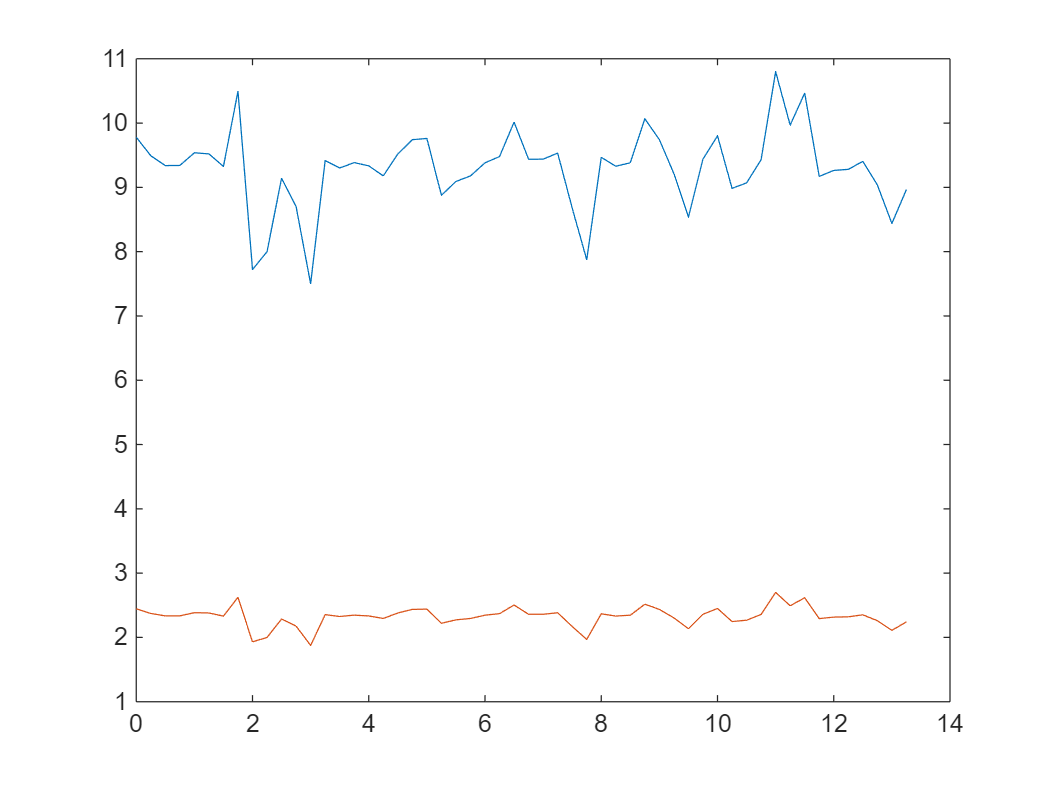

% --- Plot pace and time per section (linear model) ---
plot(sections, adjusted_pace_per_section);
hold on;
plot(sections,time_per_section);

time_per_section_hhmmss = minutes(time_per_section);
time_per_section_hhmmss.Format = 'hh:mm:ss';

% --- Calculate grade-adjusted pace for each window (exponential model) ---
adjusted_pace_per_section_exp = zeros(height(sections),1);
for i=1:height(sections)
    curelevgain = avg_gain_arr(i);
    % Normalize elevation gain to [0,1]
    norm_gain = (curelevgain - minelevgain) / (maxelevgain - minelevgain);
    % Exponential interpolation between max_pace and min_pace
    adjusted_pace_per_section_exp(i) = max_pace * (min_pace/max_pace) ^ norm_gain;
    % Alternatively: adjusted_pace = max_pace * exp( norm_gain * log(min_pace/max_pace) );
end

% --- Scale exponential model paces to match target total_time_min ---
time_per_section_exp = window_size .* adjusted_pace_per_section_exp;
tot_time = sum(time_per_section_exp);
scaling_factor = total_time_min / tot_time;
adjusted_pace_per_section_exp = adjusted_pace_per_section_exp * scaling_factor;

% --- Recompute time per section and total estimated race time (exponential model) ---
time_per_section_exp = 0.25 .* adjusted_pace_per_section_exp;
% --- Convert total race time to hh:mm:ss format ---
tot_time_exp = sum(time_per_section_exp); % in minutes
racetime = minutes(tot_time_exp);
racetime.Format = 'hh:mm:ss';
racetime

racetime = duration
   02:05:00
